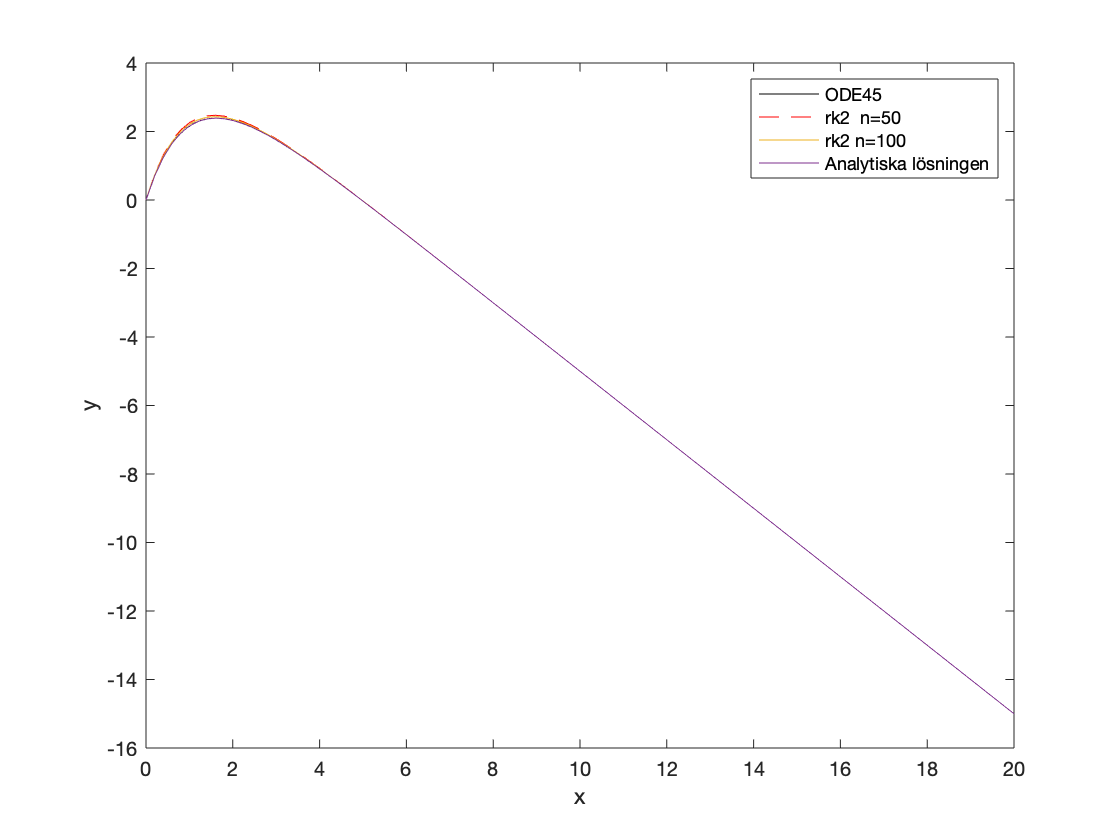

clf
%NUMERISK LÖSNING
[t1,y1] = ode45(@ysys,[0,10],[0,4]);
plot(t1,y1(:,1),'k'); 
hold on

%NUMERISK LÖSNING 
%Depending on what value n is, it will either be less or more
%accurate/similar to ode45.
[t2,z1] = rk2(@ysys,[0,10],[0, 4], 50);
plot(t2,z1(:,1),'--r');

[t3,z2] = rk2(@ysys,[0,10],[0, 4], 100);
plot(t3,z2(:,1));

%ANALYTISK LÖSNING
t = linspace(0,20,100);
c1 = 5;
c2 = -5;
ye = c1+(c2*exp(-t))-t;
plot(t,ye);

hold off
xlabel('x');
ylabel('y')
legend('ODE45', 'rk2  n=50','rk2 n=100','Analytiska lösningen');

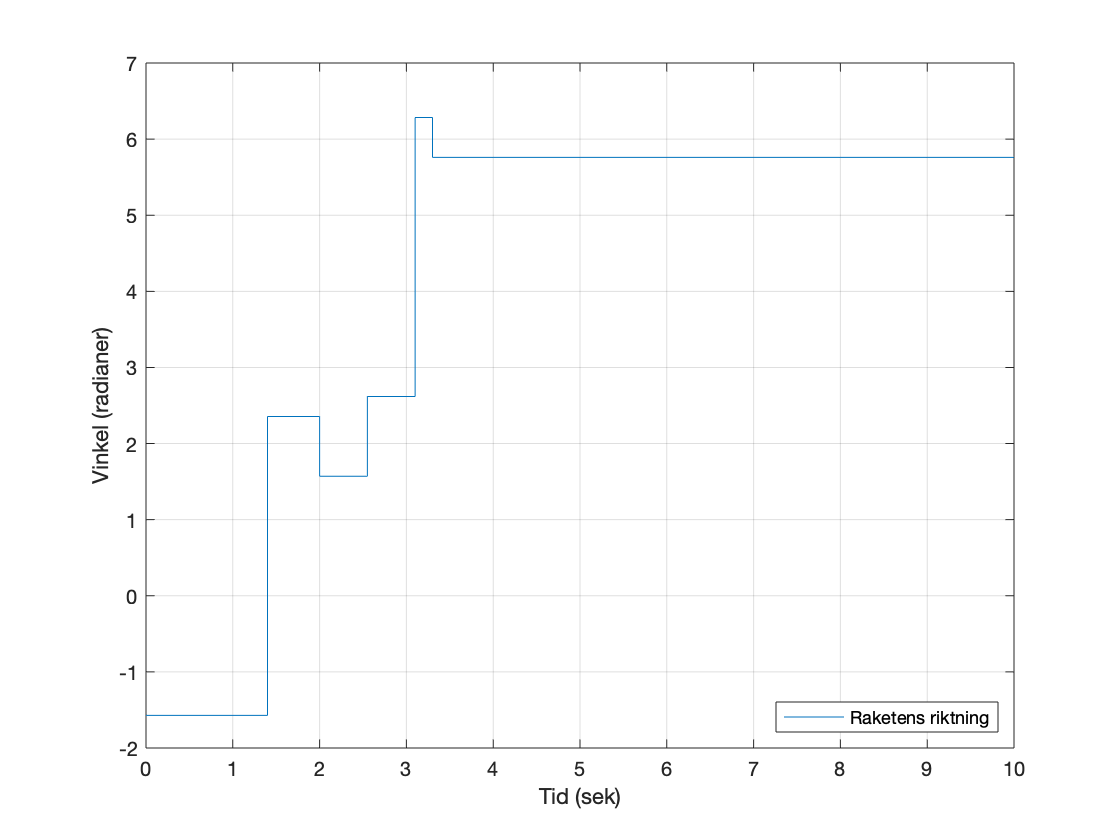


%xlim([-0.01 5.31])
%ylim([-2.52 3.41])
%-------------------------------------------------------------
%Vinkel beroende på tid
tidvinkel = [0, 1.4, 1.4, 2, 2, 2.55, 2.55, 3.1, 3.1, 3.3, 3.3, 10];
vinkel = [-pi/2, -pi/2, 3*pi/4, 3*pi/4, pi/2, pi/2, 5*pi/6, 5*pi/6, 2*pi, 2*pi, 11*pi/6, 11*pi/6];
plot(tidvinkel, vinkel);
grid on
legend('Raketens riktning', 'Location', 'southeast')
xlabel('Tid (sek)');
ylabel('Vinkel (radianer)');

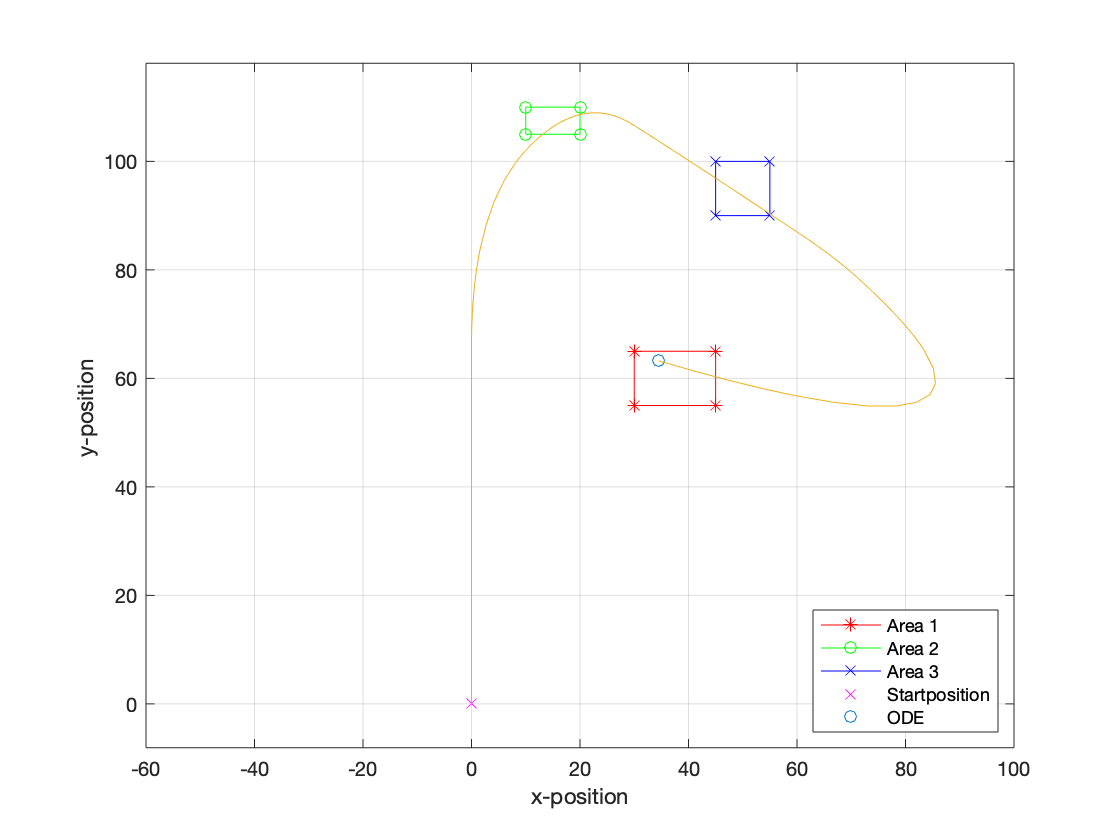


%--------------------------------------------------------------

%De olika målområden av följande x- och y-koordinater
A = [30 45 45 30 30; 55 55 65 65 55];
B = [10 20 20 10 10; 105 105 110 110 105];
C = [45 55 55 45 45; 90 90 100 100 90];
D = [0;0]; %Startpositionen

%Ritar ut målområderna 1,2 och 3
plot(A(1,:), A(2,:),'r-*'); hold on
plot(B(1,:), B(2,:),'g-o');
plot(C(1,:), C(2,:),'b-x'); 
plot(D(1,:), D(2,:), 'mx'); 

grid on, axis equal

%x = linspace(-60,80);
xlim([-60 100])
%ylim([-10 120])

%numeriska lösningar till system av differentialekvationer
% x(0)=0, y(0)=0, startpositionen (0,0)
[t4,y2] = ode45(@kast,[0 4.9], [0 0 0 0]);
%comet(y2(:,1),y2(:,3))
plot(y2(:,1),y2(:,3),'k')

%title('Raket');
xlabel('x-position');
ylabel('y-position ');
legend('Area 1', 'Area 2', 'Area 3','Startposition', 'ODE','Location','southeast');

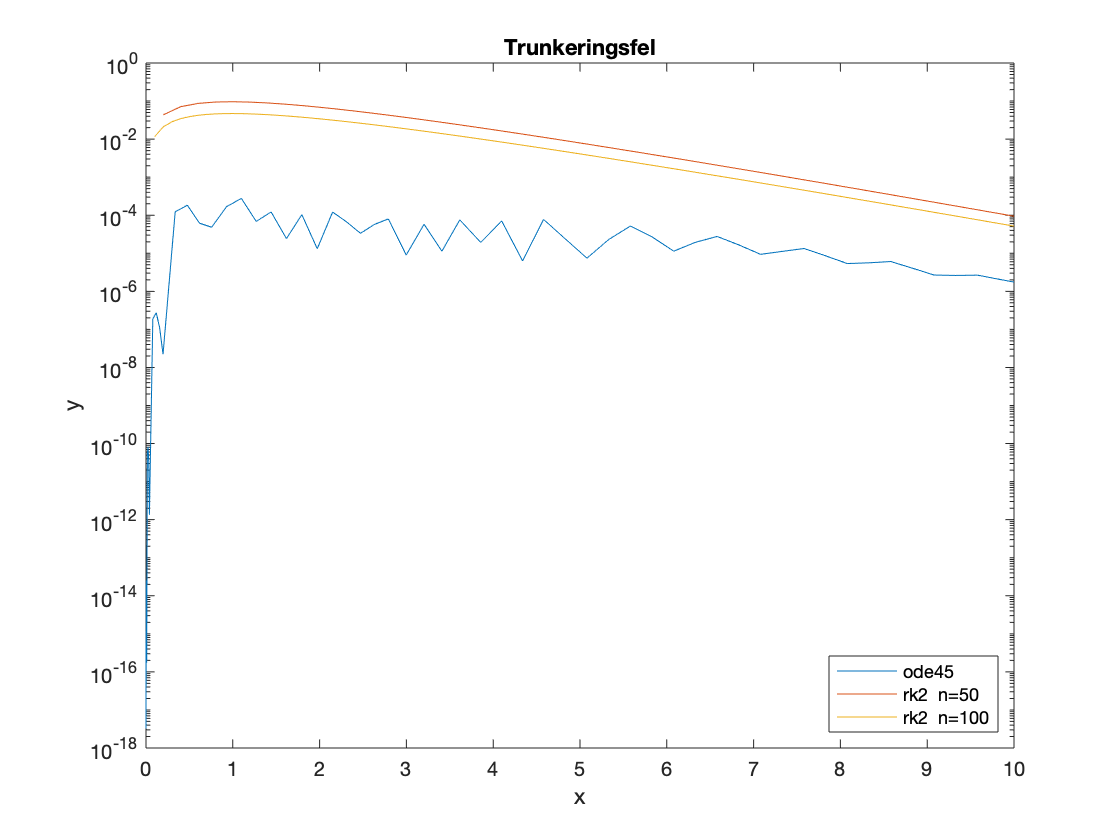


%----------------------------------------------------------
%Trunkeringsfel
 
%analytiska lösning
c1 = 5; c2 = -5;

ye1 = c1+(c2*exp(-t1))-t1;
ye2 = c1+(c2*exp(-t2))-t2;
ye3 = c1+(c2*exp(-t3))-t3;

fel1 = abs(ye1 - y1(:,1));
fel2 = abs(ye2' - z1(:,1));
fel3 = abs(ye3' - z2(:,1));

clf
semilogy(t1,fel1)
hold on

semilogy(t2,fel2)
semilogy(t3,fel3)
hold off

title('Trunkeringsfel');
legend('ode45', 'rk2  n=50', 'rk2  n=100', 'Location', 'southeast');
xlabel('x');
ylabel('y');


%medelvärdet
mean(fel1) %ode45

ans = 2.9701e-05

mean(fel2) %rk2 n=500

ans = 0.0248

mean(fel3) %rk2 n=1000

ans = 0.0125